# Advection Diffusion Reaction Equation in 1D with homogeneous Dirichlet-Neumann boundary conditions.

The following differential problem is given;

$\left\lbrace\begin{array}{cc}
 -(\mu u')' + \beta u' + \sigma u = f  \quad  x \in (0,2) 
\\
 u(0) = 0
\\
 u'(2) = 0
\end{array}
$ ,     

with $\mu(x) = 1 + x, \quad \beta(x) = -3x, \quad \sigma(x) = e^{-x}$ and $f$ such that $u\left(x\right)={\left(x-2\right)}^2 \;-\;4$ is the classical solution of the problem.

The following code implements Galerkin discretization method for the solution of the problem with an equally-spaced partition (the size of each element is equal to h). The procedure is the same described in "Homogeneous_Dirichlet_boundary_problem", with an important difference in the costruction of the stiffness matrix.

The objective is to estimate the functional relation between the size of each element and the error of the numerical solution (calculated with an approximation of the $L^{2}(0,1)$ standard norm).

We also estimate the value of the derivative of the approximate solution in $x = 2$ with a finite centered difference and the value of the approximate solution in $x = 1$, comparing them to the exact ones.

c = 0;
d = 2;
l = 1:8;
h = (1/2).^(l);
H = length(h);

mu_x = @(x) 1 + x;
beta_x = @(x) -3*x;
sigma_x = @(x) exp(-x);

%f = @(x) (-0.25*pi.*cos(0.25*pi.*x)) + (pi.^2).*(1/16).*(1 + x).*(sin(0.25*pi.*x)) - (3/4).*(pi).*x.*cos(0.25*pi.*x) + exp(-x).*sin(0.25*pi.*x);
f = @(x) -2.*(2.*x - 1) - 6.*x.*(x - 2) + exp(-x).*((x - 2).^2 - 4);

approximate_value = ones(H,1);
error = zeros(H, 1);
derivative = ones(H,1);

u = @(x) (x - 2).^2 - 4;
%u = @(x) sin(0.25*pi*x);


- I solve the discretized problem for each $h$.

for i = 1:H

    L = 2*(1/h(i)) - 1; 
    known_term = ones(L + 1,1); 
    points = linspace(c,d, 2*(1/h(i)) + 1); 
    
    exact_solution = zeros(L + 1, 1);
   
    diagD = zeros(L + 1,1);
     
    % k = j
    for m = 1:L
        diagD(m,1) = (1/h(i))*(0.5*(mu_x(points(m)) + mu_x(points(m + 1))) + 0.5*(mu_x(points(m + 1)) + mu_x(points(m + 2))));
    end
    
    % Here I insert one more term that characterizes the Neumann-Dirichlet
    % homogeneous problem.

    diagD(L + 1, 1) = (1/h(i)).*0.5.*(mu_x(points(L + 1)) + mu_x(points(L + 2)));

    codiaginfD = zeros(L, 1);
    
    % k = j - 1
    for m = 2:(L + 1)
        codiaginfD(m - 1,1) = -(1/h(i))*(0.5*(mu_x(points(m)) + mu_x(points(m + 1))));
    end

    codiagsupD = zeros(L, 1);

    % k = j + 1
     for m = 1:(L)% - 1)
        codiagsupD(m,1) = -(1/h(i))*(0.5*(mu_x(points(m + 1)) + mu_x(points(m + 2))));
     end

    D2 = diag(diagD) + diag(codiagsupD, 1) + diag(codiaginfD, -1);

    diagC = zeros(L + 1, 1);

    % k = j
     for m = 1:L
         diagC(m,1) = (1/2)*(0.5*(beta_x(points(m)) + beta_x(points(m + 1))) - 0.5*(beta_x(points(m + 1)) + beta_x(points(m + 2))));
     end

    diagC(L + 1, 1) = (0.5)*0.5*(beta_x(points(L + 1)) + beta_x(points(L + 2)));

    codiaginfC = zeros(L, 1);
    
    % k = j - 1
     for m = 2:(L + 1)
         codiaginfC(m-1,1) = -(1/2)*(0.5*(beta_x(points(m)) + beta_x(points(m + 1))));
     end

     codiaginfC(L, 1) = -(1/2)*(0.5)*(beta_x(points(L + 1)) + beta_x(points(L + 2)));

    codiagsupC = zeros(L, 1);

    % k = j + 1
     for m = 1:(L)% - 1)
        codiagsupC(m,1) = (1/2)*(0.5*(beta_x(points(m + 1)) + beta_x(points(m + 2))));
     end
   
    C2 = diag(diagC) + diag(codiagsupC, 1) + diag(codiaginfC, -1);

   diagR = zeros(L + 1, 1);

    % k = j
     for m = 1:L
         diagR(m,1) = (1/3)*(h(i))*(0.5*(sigma_x(points(m)) + sigma_x(points(m + 1))) + 0.5*(sigma_x(points(m + 1)) + sigma_x(points(m + 2))));
     end

     diagR(L + 1, 1) = (h(i))*(1/3).*(0.5)*(sigma_x(points(L + 1)) + sigma_x(points(L + 2)));

    codiaginfR = zeros(L, 1);
    
    % k = j - 1
     for m = 2: (L + 1)
         codiaginfR(m-1,1) = (1/6)*(h(i))*(0.5*(sigma_x(points(m)) + sigma_x(points(m + 1))));
     end

    codiagsupR = zeros(L, 1);

    % k = j + 1
     for m = 1:(L) %- 1)
         codiagsupR(m,1) = (1/6)*(h(i))*(0.5*(sigma_x(points(m + 1)) + sigma_x(points(m + 2))));
     end

    R2 = diag(diagR) + diag(codiagsupR, 1) + diag(codiaginfR, -1);
     
    A2 = D2 + C2 + R2;
    
    for k = 1:(L + 1)
        if k == L + 1
            known_term(k) = 0.5*f(points(k + 1));
            exact_solution(k) = u(points(k + 1));
            break;
        end
        known_term(k) = f(points(k + 1));
        exact_solution(k) = u(points(k + 1));
    end
    
    known_term = h(i)*known_term;

    u_h = A2\known_term;
    
    approximate_value(i,1) = u_h((length(u_h))/2)


    for k = 1:length(exact_solution)
        error(i) = error(i) + (h(i)*(abs(exact_solution(k) - u_h(k)))^2);
    end

    error(i) = sqrt(error(i));

    if i == H
         plot_points = ones(length(points) - 1, 1);
  
         for p = 1:length(plot_points)
             plot_points(p) = points(p + 1);
         end

         plot(plot_points, u_h);
         hold on 
         plot(plot_points, exact_solution);
    end

    derivative(i) = (1/(2*h(i)))*(u_h(length(u_h)) - u_h(length(u_h) - 2));

end

approximate_value =    -5.5567
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


approximate_value =    -5.5567
   -3.6271
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


approximate_value =    -5.5567
   -3.6271
   -3.1562
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


approximate_value =    -5.5567
   -3.6271
   -3.1562
   -3.0390
    1.0000
    1.0000
    1.0000
    1.0000


approximate_value =    -5.5567
   -3.6271
   -3.1562
   -3.0390
   -3.0097
    1.0000
    1.0000
    1.0000


approximate_value =    -5.5567
   -3.6271
   -3.1562
   -3.0390
   -3.0097
   -3.0024
    1.0000
    1.0000


approximate_value =    -5.5567
   -3.6271
   -3.1562
   -3.0390
   -3.0097
   -3.0024
   -3.0006
    1.0000


approximate_value =    -5.5567
   -3.6271
   -3.1562
   -3.0390
   -3.0097
   -3.0024
   -3.0006
   -3.0002


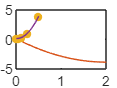


coeff = polyfit(h, error, 2);

y = @(x) coeff(1)*x.^2 + coeff(2)*x + coeff(3);

poin = linspace(h(length(h)), h(1));
y_poin = y(poin);

plot(h, error, '.', 'markersize', 14)
hold on
plot(poin, y_poin)

- The functional relation between the discretization error and the uniform size of each element by a quadratic fit of the data is:

$err(h) = c_{1} \cdot h^{2} + c_{2} \cdot h + c_{3}$, 

with $c_1$ = coeff(1) = 15.9, $c_{2}$ = coeff(2) = -0.436, $c_3$ = coeff(3) =  0.00822.

Remark:  for very low value of the element size the function $y = c_{1} \cdot x^{2}$ gives a better approximation of the experimental data than the function above mentioned.

derivative

derivative =    -1.6471
   -0.6023
   -0.2710
   -0.1298
   -0.0636
   -0.0315
   -0.0157
   -0.0078


approximate_value

approximate_value =    -5.5567
   -3.6271
   -3.1562
   -3.0390
   -3.0097
   -3.0024
   -3.0006
   -3.0002


- The value of the derivative of the approximate solution in x = 2 converges to the exact null value, as the vector "derivative" shows (the numerical derivative is calculated with a finite centered difference).

- The approximate value in x = 1 also converges to exact one (which is equal to -3).